syms W_11 W_12 W_21 W_22 x_1 x_2 x_3 W_1 W_2 W_3 W_4 real

w = [W_11, W_12;W_21, W_22]

w.*x

W = [W_1; W_2; W_3];
x = [x_1;x_2;x_3];
W.*x

t = train_input(:,3)
b = w*t-theta

b = 0;
for k=1:2
    b = b + w(3,k)*t(k);
end
b

V = tanh(b);
W(1)*V(1)+W(2)*V(2)+W(3)*V(3)
W*V

mu = randi([1,p]);
x_mu = train_input(:,mu); % randomly pick an input from training set
t_mu = target(mu);

% propagate forward
b_mu = w*x_mu-theta;
V = tanh(b_mu);  % activation function g = tanh()
B_mu = dot(W,V)-Theta;
Out = tanh(B_mu)
diff(tanh(B_mu))

syms x real
f = tanh(x);
diff(f)
g = eval(subs(diff(f),0.03))

B_m = B_mu
t_m = target(mu);
Out_m = Out;
g_prime = eval(subs(diff(f), B_m))
Delta_m = (t_m-Out_m) * g_prime;
delta_W = eta * Delta_m * V'
W = W + delta_W

B = B_mu
t = target(mu);
g_prime_B = eval(subs(diff(f), B))
Delta = (t - Out) * g_prime;
delta_W = eta * Delta * V';
W = W + delta_W;

% assume m=1
delta_w = zeros(size(w));
delta_theta = zeros(size(theta));
for n = 1:N
    x_n = x_mu(n);
    for m = 1:M
        b_m = b_mu(m);
        g_prime_b_m = eval(subs(diff(f), b_m));
        delta_m = Delta * W(m) * g_prime_b_m;
        delta_theta(m) = -eta * delta_m;
        delta_w(m,n) = eta * delta_m * x_n;
    end
end
delta_w
w = w + delta_w

eval(subs(diff(f), b_mu))
delta_m = Delta*W'.*eval(subs(diff(f), b_mu))
delta_w = eta * delta_m *x_mu'

H=[];
H(end+1)=0.1;
H(end+1)=0.4;
H(end+1)=1;
H(end+1)=2;
H(end+1)=3;
H(end+1)=6;
H2 = H;
H = flip(H);
figure
hold on
plot(1:epoch_n,log(H))
plot(1:epoch_n,log(H2))
legend('H\_train','H\_val')
hold off

w;
w*validation_input
b = w*validation_input-theta
V = tanh(b)
B = W*V-Theta
C = 1/(2*p_val)*sum(abs(validation_target'-sign(B)))

tmp = 0;
for mu = 1:p_val
    x_mu = validation_input(:,mu);
    b_mu = w * x_mu - theta;    % [Mx1]
    V = tanh(b_mu);         % activation function g = tanh()
    B_mu = W * V - Theta;  % scalar
    Out = tanh(B_mu);       % scalar
    tmp = tmp + abs(validation_target(mu)-sign(Out));
end
C = 1/(2*p_val)*tmp

x1 = [1;1];
x2 = [2;2];
x3 = [3;3];
x = [x1,x2,x3]

x =      1     2     3
     1     2     3


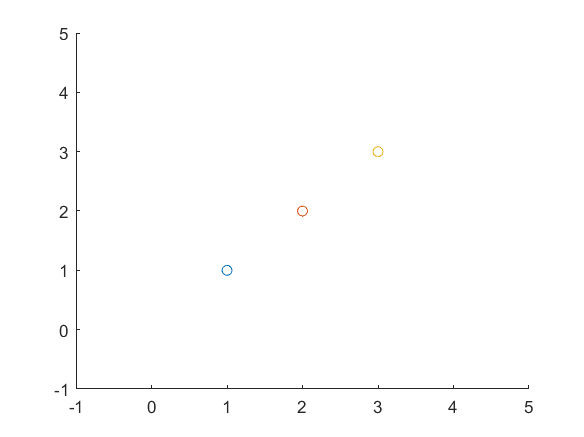

figure
for i =1:3
    scatter(x(1,i), x(2,i))
    xlim([-1,5])
    ylim([-1,5])
    hold on
    pause(1)
end

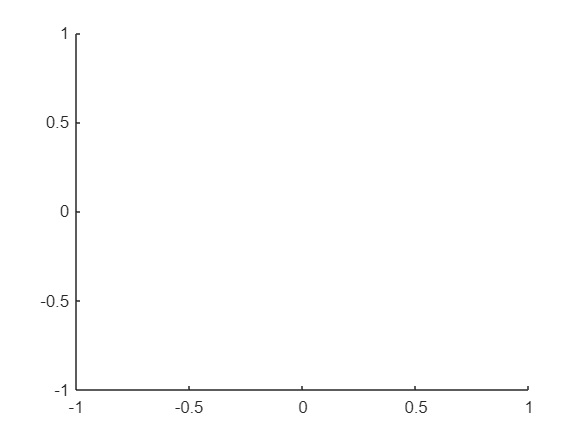

figure
hold on
plot(1,1)
plot(2,2)
xlim([-1,1])
ylim([-1,1])